# Harddisk drive position control

Using RST design

The Diophantine equation becomes

$A(z)(z-1)R(z) + B(z)S(z) = A_{c}(z)A_o(z)  $.

 The Diophantine equation will give $\deg(A) + \deg(R) + 1$ linear equations, and the number of unknown parameters in the controller


$$F_b(z) = \frac{s_0z^{n+1} + s_1z^{n} + \cdots + s_{n+1}}{(z+1)(z^n + r_1z^{n-1} + \cdots + r_n)}$$


is $n+n+2=2\deg R + 2$.

Setting the number of equations equal to the number of unknown parameters gives

$\deg{R} = \deg{A} +1-2 = \deg{A} - 1 = 1$.

Hence, the controller is

$F_b(z) = \frac{s_0z^2 + s_1z + 1}{(z-1)(z+r_1)}$.

The LHS of the Diophantine equation is of degree 4. The desired closed-loop characteristic polynomial is $A_c(z) $ which is of degree 2. That means we have two observer poles to place. Place this in the origin for a deadbeat (fastest possible) observer.

% Kjartan Halvorsen 
% 2021-07-20


% Parameters
l = 1*2.54/100; % Length from CoM to axis
m = 9.83e-4; %kg
J = 4.78e-7 + m*l*l;

% Continuous-time model
s = tf('s');
G = (1/J)/s^2;

h = 2e-4; % Sampling period
Gd = c2d(G, h)

Gd =
 
  0.01798 z + 0.01798
  -------------------
     z^2 - 2 z + 1
 
Sample time: 0.0002 seconds
Discrete-time transfer function.



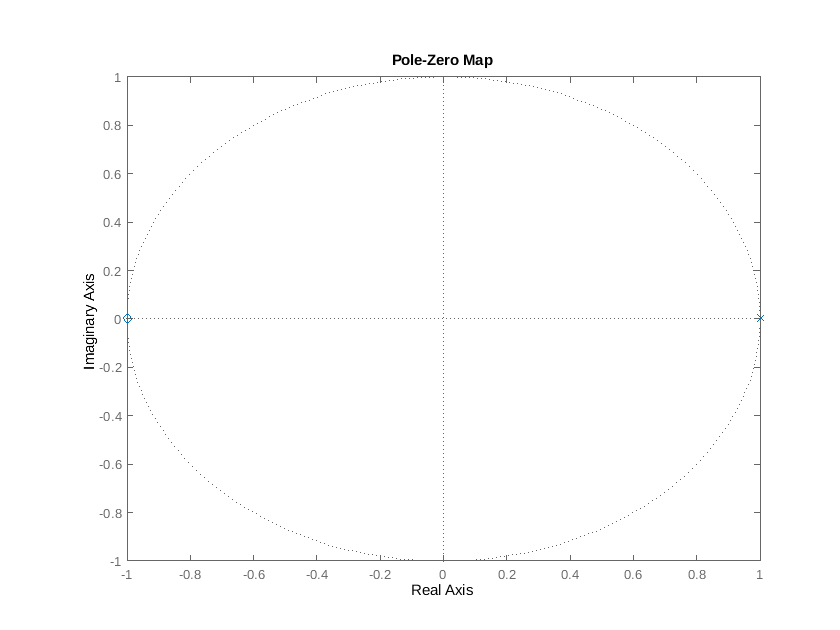

[num, den] = tfdata(Gd);
A = den{1};
B = num{1};

% For symbolic computations
syms z
As = poly2sym(A, z); % Generates polynomial A(1)*z^nA + A(2)*z^(nA-1) + ...
Bs = poly2sym(B, z);

pzmap(Gd)



% Desired characteristic polynomial
p1 = 0;
p2 = conj(p1);
Ac = conv([1, -p1], [1, -p2]);
Acs = poly2sym(Ac, z);

%------------------------------------
% Solve using symbolic math toolbox!
%------------------------------------

% Controller polynomials
r = [1, sym('r1')];
s = sym('s', [1, 2]); % Vector starts with s1
s = cat(2, sym('s0'), s); % Now it starts with s0
Rs = poly2sym(r, z);
Ss = poly2sym(s, z);
    

% Left hand side of Diophantine eqn
disp('Left hand side of Diophantine eqn')

Left hand side of Diophantine eqn


LHS = collect(As*(z-1)*Rs + Bs*Ss, z)

$$LHS = z^{4}+\left(r_{1}+\frac{5183103341658005\,s_{0}}{288230376151711744}-3\right)\,z^{3}+\left(\frac{2591551670829003\,s_{0}}{144115188075855872}-3\,r_{1}+\frac{5183103341658005\,s_{1}}{288230376151711744}+3\right)\,z^{2}+\left(3\,r_{1}+\frac{2591551670829003\,s_{1}}{144115188075855872}+\frac{5183103341658005\,s_{2}}{288230376151711744}-1\right)\,z+\frac{2591551670829003\,s_{2}}{144115188075855872}-r_{1}$$


% Right hand side
p0 = 0; % observer pole
Ao = poly2sym([1, -p0], z) * poly2sym([1, -p0], z);
disp('Right hand side of Diophantine eqn')

Right hand side of Diophantine eqn


RHS = collect(Acs*Ao, z)

$$RHS = z^{4}$$


% Coefficients
LHScoeffs = coeffs(LHS, z, 'All'); % Coefficients in increasing power of z
RHScoeffs = coeffs(RHS, z, 'All');

% Set up system of equations and solve
unknowns = cat(2, r(2:end), s);
sol = solve(LHScoeffs(2:end) - RHScoeffs(2:end), unknowns); %

% Find t0 as Ac(1)/B(1)
t0 = subs(Acs, z, 1) / subs(Bs, z, 1);

% Substitute numerical values

s0_n = double(sol.s0);
s1_n = double(sol.s1);
s2_n = double(sol.s2);
r1_n = double(sol.r1);
t0_n = double(t0);

R_c = conv([1, -1], [1, r1_n]);
S_c = [s0_n, s1_n, s2_n];
T_c = t0_n*double(coeffs(Ao, z, 'All')) 

T_c =    27.8048         0         0




% Define the controller
F_fb_c = tf(S_c, R_c, h);
F_ff_c = tf(T_c, R_c, h);

% Closed-loop system from command signal to output
Hc_c = minreal(F_ff_c * feedback(Gd, F_fb_c))

Hc_c =
 
           0.5 z + 0.5
  -----------------------------
  z^2 - 8.866e-25 z + 5.551e-16
 
Sample time: 0.0002 seconds
Discrete-time transfer function.




% Closed-loop system from command signal to control signal
Huc_c = minreal(F_ff_c * feedback(1, Gd*F_fb_c));

% Closed-loop system from disturbance signal to output
Hvc_c = minreal(feedback(1, Gd*F_fb_c));


## Plot responses

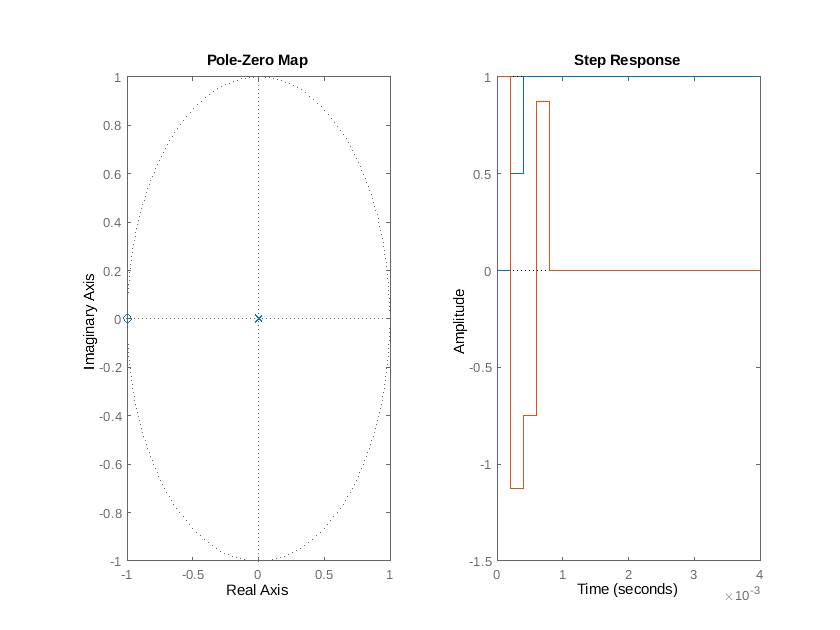


figure()
clf
subplot(121)
pzmap(Hc_c)
subplot(122)
step(Hc_c, Hvc_c)

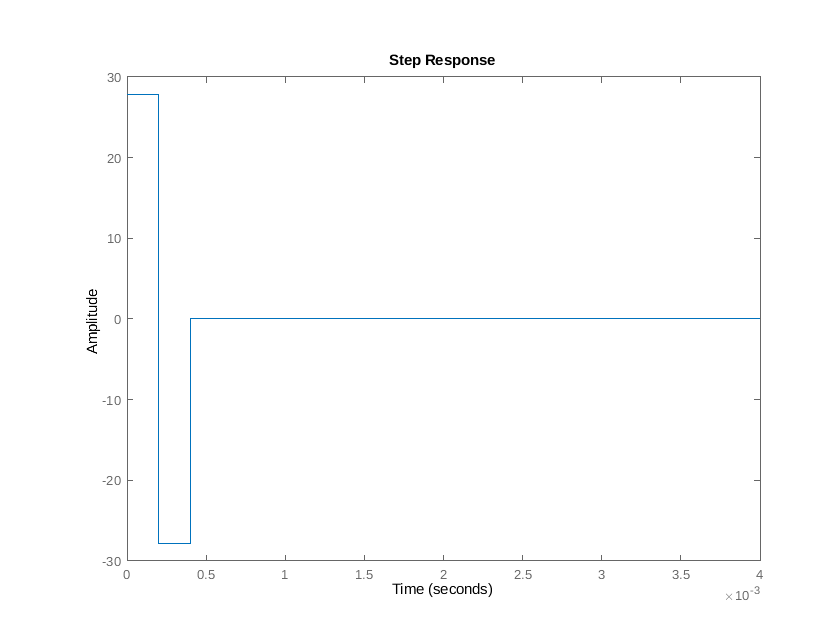

figure()
step(Huc_c)